% Image Object Vertices Visualizer

clear; close all;

% Select image file
[im_name,path1] = uigetfile('*.*', "Select an Image File");
im = imread(strcat(path1, im_name));

% Select rotation vector (angle for each frame)
[vert_name,path2] = uigetfile('*.*', "Select a Vertex Data File");
vert_vec = readmatrix(strcat(path2, vert_name));
vert_vec % display

vert_vec =    312   279
   473   194
   484   343
   647   275


vert_vec(:,2) = size(im,1) - vert_vec(:,2);
vert_vec % display

vert_vec =    312   261
   473   346
   484   197
   647   265


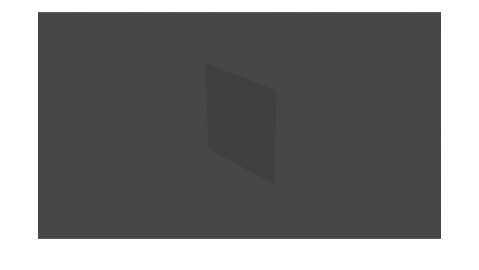

% Display Image
imshow(im)

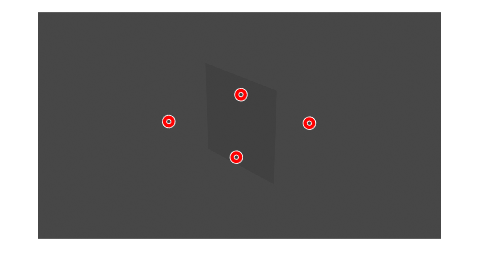

% Circle the Verteces
viscircles(vert_vec, 10);